 %% 1. PHYSICAL CONSTANTS & SYSTEM MATRICES
m_pendulum = 13/1000; r = 50/1000; l = 5/1000; 
J_arm = 10.771075439837363; motor_b = 0.523596450597066; 
motor_k = 1.1493; motor_r = 0.136144129960745;
motor_eff = 0.69; gear_eff = 0.9; gear_ratio = 1;

% Derived constants
a = J_arm + (m_pendulum*r*r);
b = m_pendulum*l*r;
c = (4/3)*m_pendulum*l*l;
d = m_pendulum*9.8*l;
e = (a*c)-(b*b);

G = ((motor_eff*gear_eff*motor_k*motor_k*(gear_ratio^2))-(motor_b*motor_r))/(motor_r);
H = (motor_eff*gear_eff*motor_k*gear_ratio)/(motor_r*e);

% State Space Matrices
A_mat = [0 0 1 0; 
         0 0 0 1; 
         0 (b*d/e) (-(c*G)/e) 0; 
         0 (a*d/e) (-b*G)/e 0];
B_mat = [0; 0; (c*H); (b*H)];

%% 2. DEFINE OPTIMIZATION VARIABLES (All 4 States + R)
% We use log scales to search across orders of magnitude
q_theta     = optimizableVariable('q_theta', [1, 2000], 'Transform', 'log');
q_alpha     = optimizableVariable('q_alpha', [500, 20000], 'Transform', 'log');
q_theta_dot = optimizableVariable('q_theta_dot', [0.1, 100], 'Transform', 'log');
q_alpha_dot = optimizableVariable('q_alpha_dot', [1, 1000], 'Transform', 'log');
r_weight    = optimizableVariable('r_val', [0.01, 50], 'Transform', 'log');

vars = [q_theta, q_alpha, q_theta_dot, q_alpha_dot, r_weight];

%% 3. START TUNING LOOP
disp('Starting Full-State Autotune on Arduino...');

Starting Full-State Autotune on Arduino...


|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |      q_theta |      q_alpha |  q_theta_dot |  q_alpha_dot |        r_val |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |
|==================================================================================================================================================|
|    1 | Best   |       1e+07 |     0.13926 |       1e+07 |       1e+07 |       9.2967 |       971.29 |        43.67 |       2.0515 |       39.269 |
|    2 | Accept |       1e+07 |    0.011607 |       1e+07 |       1e+07 |       8.4286 |        13696 |       24.298 |       402.44 |       14.036 |
|    3 | Accept |       1e+07 |   0.0086872 |       1e+07 |       1e+07 |       840.49 |       565.93 |   

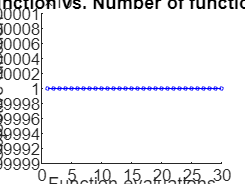

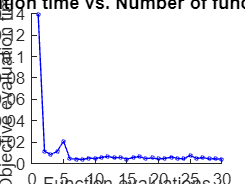

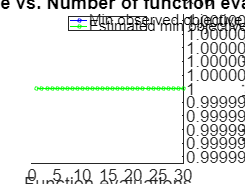

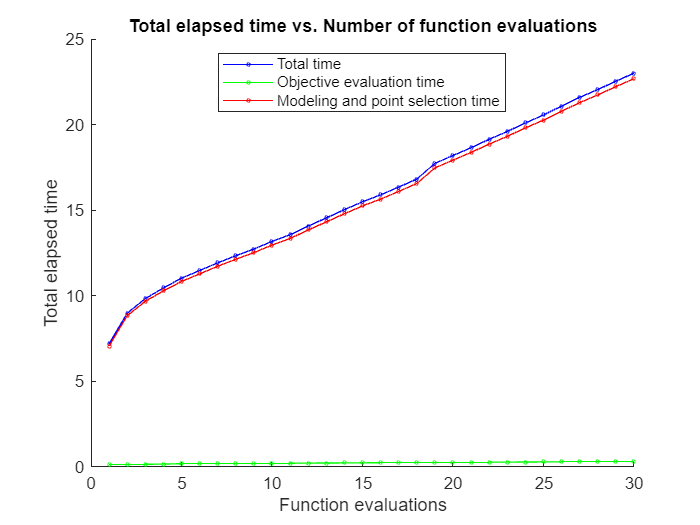

results = bayesopt(@(x) run_hil_iteration(x, A_mat, B_mat), vars, ...
    'MaxObjectiveEvaluations', 30, ... % Increased evaluations for 5 variables
    'PlotFcn', 'all', ...
    'AcquisitionFunctionName', 'expected-improvement-plus');


%% 4. OBJECTIVE FUNCTION
function score = run_hil_iteration(params, A, B)
    model_name = 'HIL_2';
    block_path = 'HIL_2/controllers/-k*uvec';
    
    % 1. Construct Q and solve LQR
    Q = diag([params.q_theta, params.q_alpha, params.q_theta_dot, params.q_alpha_dot]); 
    R = params.r_val;
    
    try
        [K, ~, ~] = lqr(A, B, Q, R);
        
        % 2. Push gain as a single-precision string
        % This prevents the 'double' to 'single' runtime data type error
        K_str = mat2str(single(K));
        set_param(block_path, 'Gain', K_str);
        
        fprintf('Testing: [Th: %.1f, Al: %.1f, ThD: %.1f, AlD: %.1f, R: %.2f]\n', ...
            params.q_theta, params.q_alpha, params.q_theta_dot, params.q_alpha_dot, params.r_val);
        
        % 3. Collection Window (Wait for hardware response)
        pause(5); 
        
        % 4. Analyze results from Simulation Data Inspector
        run = Simulink.sdi.getCurrentSimulationRun;
        sig = run.getSignalByIndex(1); % Ensure index 1 is your pendulum angle alpha
        
        t = sig.Values.Time;
        e = sig.Values.Data;
        
        % Calculate ITAE Cost (minimize this)
        score = sum(t .* abs(e));
        
        % If the pendulum fell (angle too high), penalize the score
        if max(abs(e)) > 0.5 % Approx 30 degrees
            score = score * 2;
        end
        
    catch
        score = 1e7; % Massive penalty for instability or connection loss
    end
end